# Simulink Model of Muscle Spindle

Write a single main script **hwsimulink.mlx** that demonstrates your answers to the following problems.

- Implement Muscle Spindle Model in Simulink. Save it as musclespindle.slx

- Save a snapshot of your model as musclespindle.png. Include this image in your notebook.

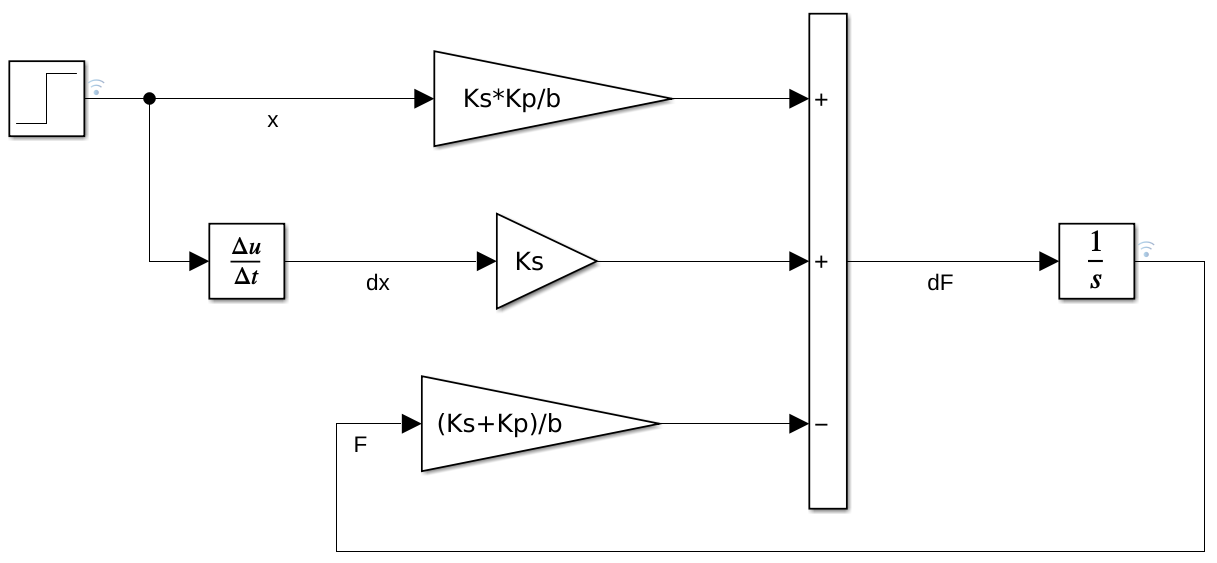

- Simulink Options:

-     Use simtime <1sec (You may further adjust this to display plots that demonstrate the full behavior of the system).

-     Change SolverType: Fixed Step size: 0.0001

-     Provide a step input for x, at time=0.1, taking x from 0 to 1.

- Simulate the model from a matlab script/function. Use Kp=0.2, Ks=1.5, and b=0.025. Plot the F vs. time.

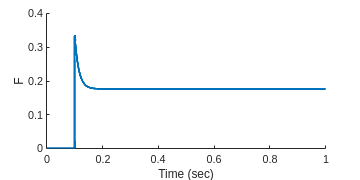

clear

% simulation opts and parameters
step_time = 0.1;
x_value = 1;

% define model parameters
Kp = 0.2;
Ks = 1.5;
b = 0.025;

% run simulation
load_system('musclespindle.slx');
out = sim('musclespindle.slx');

% extract data
F = out.logsout.get('F').Values;
x = out.logsout.get('x').Values;
pkF = max(F.Data);
eqF = F.Data(end);

% plot results
figure('Position', [0 0 400 200]); hold on;
plot(F, 'LineWidth', 2);
xlabel('Time (sec)'); ylabel('F')

- Parameter sensitivity analysis. For each of the following parameter variations, report the peak force and the equilibrium force. Report all of these conditions in a table with columns Kp, Ks, b, PeakForce, EquilibriumForce.

- Using the default Kp, Ks, and b.

-     Kp increased 2-fold. Decreased to 1/2-fold. (Other variables kept at their defaults.)

-     Ks increased 2-fold. Decreased to 1/2-fold. (Other variables kept at their defaults.)

-     b increased 2-fold. Decreased to 1/2-fold. (Other variables kept at their defaults.)

% default values for each parameter
Kp = 0.2;
Ks = 1.5;
b = 0.025;
defaults = [Kp Ks b];
multiplier = [0.5 2.0];
columns = {'Kp', 'Ks', 'b', 'PeakForce', 'EquilibriumForce'};

% preallocate for loop
data = zeros([numel(defaults) * numel(multiplier), 5]);
data(1, :) = [Kp Ks b pkF eqF];
row = 2;
for i = 1:numel(defaults) % for each param
    for j = 1:numel(multiplier) % for each multiplier
        % define current value for each param
        for k = 1:numel(defaults) % for each param (assignment)
            if i == k
                value = defaults(k) * multiplier(j);
            else
                value = defaults(k);
            end
            assignin('base', columns{k}, value)
        end

        % run simulation, extract peak/eq force
        out = sim('musclespindle.slx');
        F = out.logsout.get('F').Values;
        pkF = max(F.Data);
        eqF = F.Data(end);
        
        % store data
        data(row, :) = [Kp Ks b pkF eqF];
        row = row + 1;
    end
end

% display results
T = array2table(data, 'VariableNames', columns);
display(T);

T = 7×5 table
    Kp      Ks       b       PeakForce    EquilibriumForce
    ___    ____    ______    _________    ________________

    0.2     1.5     0.025     0.33284         0.17647     
    0.1     1.5     0.025     0.33234         0.09375     
    0.4     1.5     0.025     0.33384         0.31579     
    0.2    0.75     0.025     0.16679         0.15789     
    0.2       3     0.025     0.66273          0.1875     
    0.2     1.5    0.0125     0.33236         0.17647     
    0.2     1.5      0.05     0.33309         0.17647     
